# Lab Activity on descriptive statistics and data visualization

Download from the Files section of the Teams of the course the datafile dataBO.dat, which contains daily temperature (minimum and maximum) and rain recordings in Bologna in 1961-2018.  

Consider in particular both the daily (minimum and maximum) temperature (°C) and average monthly rain (mm) recorded in 2018, and compare them with the average values in the previous 10 years (2008-2017). 

%% 1) Load the data
clear all
close all
clc

% General settings
site = 'Bologna';
month_labels = {'JAN','FEB','MAR','APR','MAY','JUN',...
          'JUL', 'AUG', 'SEP', 'OCT', 'NOV', 'DEC'};

% Select the file containing the data
[filename,path] = uigetfile('*.dat');

if isequal(filename,0)
   disp('User selected Cancel');
   clear all
   return
else
   disp(['User selected ', fullfile(path,filename)]);
end

User selected /home/omismone/dev/MATLAB/abds/abds_group6/lab1/dataBO.dat


data = readtable(fullfile(path,filename));

% Rain = data.Rain;
% Tmax = data.Tmax;
% Tmin = data.Tmin;
% Tmean = mean([Tmin'; Tmax']);

% The data are saved into a Table object.
% Dates are stored into MATLAB datetime datatypes... Type doc datetime to see how to use it.

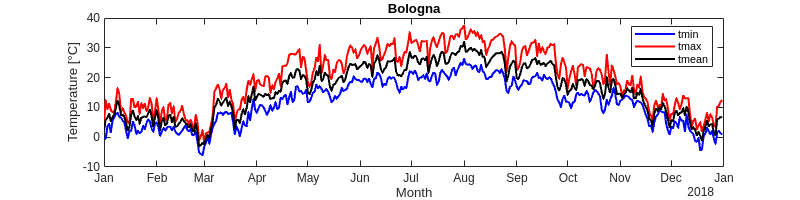

%% 2) Plot 2018 data samples
% select the 2018 data 
data_2018 = data(year(data.Date) == 2018,:);
% display the 2018 temperature
figure(1)
set(gcf,'position',[100 100 800 200])
plot(data_2018.Date,data_2018.Tmin, "b", "DisplayName","tmin", "LineWidth", 1.5)
hold on
plot(data_2018.Date,data_2018.Tmax, "r", "DisplayName","tmax", "LineWidth", 1.5)
hold on
plot(data_2018.Date,mean([data_2018.Tmin'; data_2018.Tmax']), "k", "DisplayName","tmean", "LineWidth", 1.5)
ylabel("Temperature [°C]")
xlabel("Month")
title(site)
hold off
legend("show")

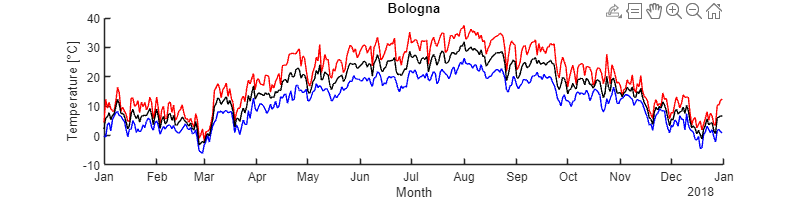

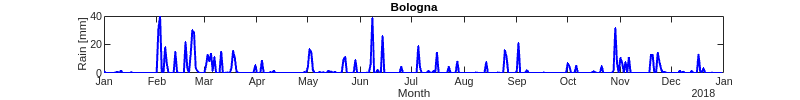

% Use plot() to display the 2018 rain...
% display the 2018 rain
figure(2)
set(gcf,'position',[100 100 800 100])
plot(data_2018.Date,data_2018.Rain, "b", "LineWidth", 1.5)
ylabel("Rain [mm]")
xlabel("Month")
title(site)

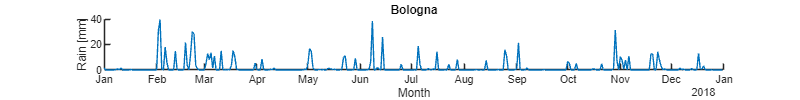

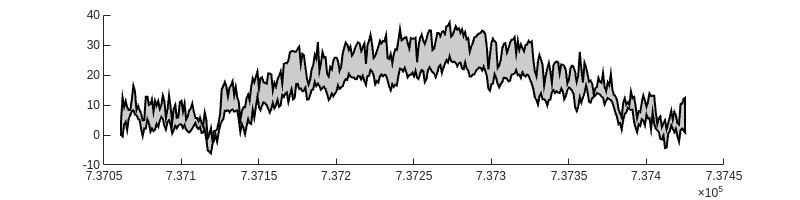

% Use patch() function to plot Tmin and Tmax in 2018 as thick lines..
figure(3)
set(gcf,'position',[100 100 800 200])
patch(datenum([data_2018.Date; flipud(data_2018.Date)]), [data_2018.Tmin; flipud(data_2018.Tmax)], [0.8 0.8 0.8], "LineWidth", 1.5)

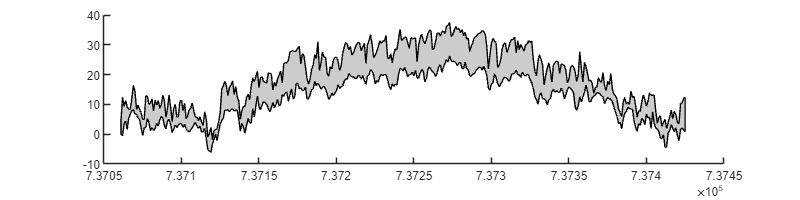

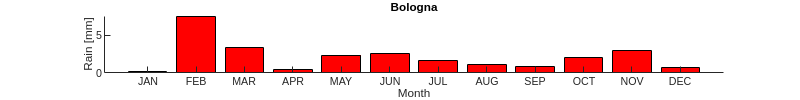

%% 3) Take monthly average
rain_means = zeros(1,12);
for m = 1:12
    rain_means(m) = mean(data_2018.Rain(month(data_2018.Date) == m));
end
% Use bar() to display the average monthly rain in 2018
figure(4)
bar(month_labels,rain_means, "r")
title(site)
ylabel("Rain [mm]")
xlabel("Month")
set(gcf,'position',[100 100 800 100])
box off
yticks([0 5])

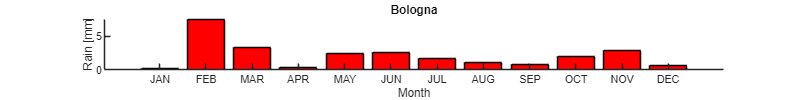

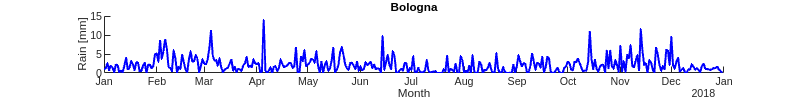

%% 4) Average and plot 2008-2017 data samplesEnoise
% Eliminate extra days in leap years to make averaging over days easier
data_2008to2017 = data(year(data.Date) >= 2008 & year(data.Date) <= 2017 & ~(day(data.Date) == 29 & month(data.Date) == 2),:);
% Average data
days = datetime(2018,1,1):datetime(2018,12,31); %random year, are used only days and months
averages = table(days',zeros(365,1), 'VariableNames', {'Date', 'Rain'});
temp_avg = table(days',zeros(365,1),zeros(365,1), 'VariableNames', {'Date', 'TMinAvg', 'TMaxAvg'});
for i = 1:length(days)
    averages{i,2} = mean(data_2008to2017.Rain(month(data_2008to2017.Date) == month(days(i)) & day(data_2008to2017.Date) == day(days(i))));
end
% Plot the 10-year average rain data
figure(5)
set(gcf,'position',[100 100 800 100])
plot(averages.Date,averages.Rain, "b", "LineWidth", 1.5)
ylabel("Rain [mm]")
xlabel("Month")
title(site)
box off

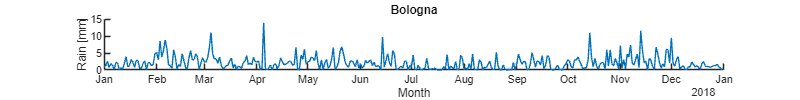

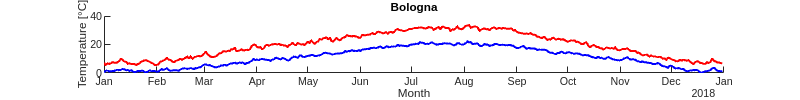

% Plot the 10-year average temperature data (min and max)
for i = 1:length(days)
    temp_avg{i,2} = mean(data_2008to2017.Tmin(month(data_2008to2017.Date) == month(days(i)) & day(data_2008to2017.Date) == day(days(i))));
    temp_avg{i,3} = mean(data_2008to2017.Tmax(month(data_2008to2017.Date) == month(days(i)) & day(data_2008to2017.Date) == day(days(i))));
end
figure(6)
set(gcf,'position',[100 100 800 100])
plot(temp_avg.Date,temp_avg.TMinAvg, "b", "LineWidth", 1.5)
hold on
plot(temp_avg.Date,temp_avg.TMaxAvg, "r", "LineWidth", 1.5)
ylabel("Temperature [°C]")
xlabel("Month")
title(site)
box off
hold off

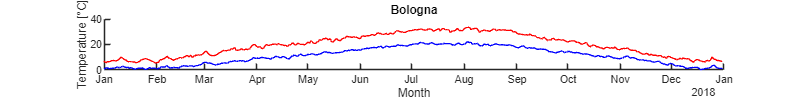

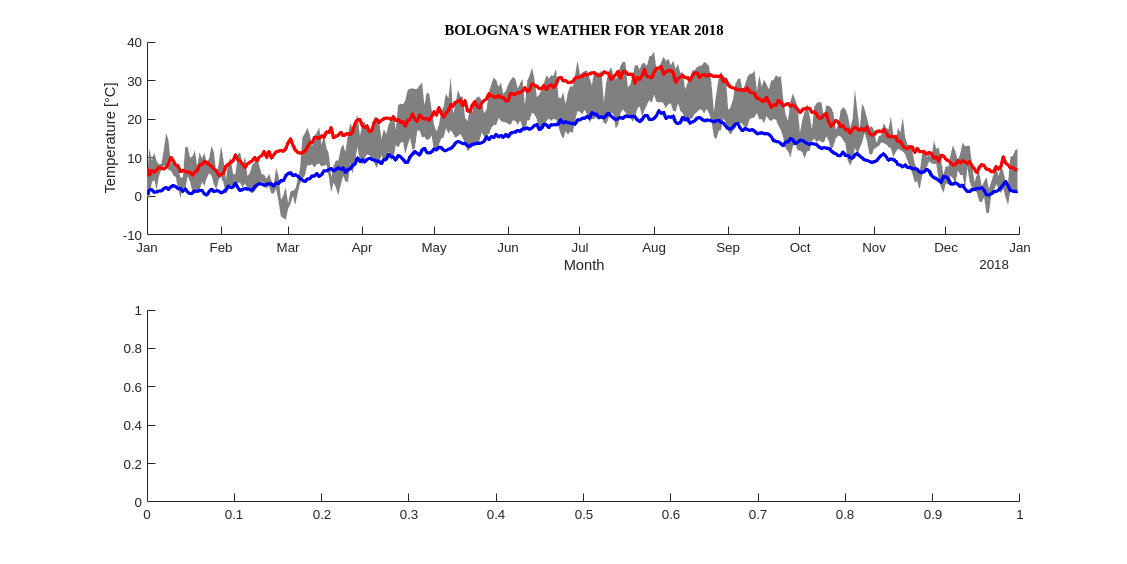

%% 5) Generate a high-quality plot

% Generate a single figure which summarizes the above data. 

% Use low-level MATLAB graphics commands and pay special attention to 
% Telling the truth; 
% Maximising the data ink ratio 
% Maximizing the data density 
% Create a figure with a suitable aspect ratio

% Create an axis suitable for plotting temperature data

%% Plot temperature data

% plot 10-year averages of Tmin and Tmax
figure(7)
subplot(2,1,1)
set(gcf,'position',[100 100 1600 800])
patch([data_2018.Date; flipud(data_2018.Date)], [data_2018.Tmin; flipud(data_2018.Tmax)], [0.5 0.5 0.5], "LineWidth", 1.5, "EdgeColor", "none")
hold on
plot(temp_avg.Date,temp_avg.TMinAvg, "b", "LineWidth", 2.5)
%text(0, 0, "LOW: " + "") 
% continue from here
plot(temp_avg.Date,temp_avg.TMaxAvg, "r", "LineWidth", 2.5)
ylabel("Temperature [°C]", "FontName", "Helvetica")
xlabel("Month", "FontName", "Helvetica")
title("BOLOGNA'S WEATHER FOR YEAR 2018", "FontName", "Times New Roman")
box off
hold off
% plot labels for lowest and highest temperatures

% uses a serif-type font which improves readability

%% Plot rain data 
subplot(2,1,2)

% Create an axis suitable for rain data

% calculate monthly average Rain in last 10 years

% plot both 2018 and 10-years average rain

% uses a serif-type font which improves readability


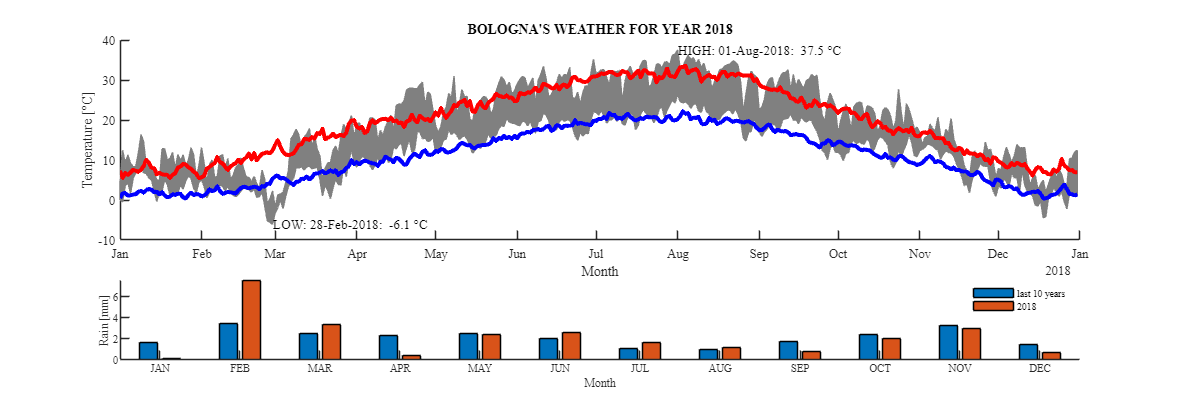

%% 6) Load a new dataset 

% This dataset refers to 30 patients tested across three times 
% to see if there was an improvement in their visual function 
% (the highest value corresponds to the best visual function) after some drug's treatments. 
% The name of data is data_lab1_vis.csv.

clear all
close all

[filename,path] = uigetfile("*.csv");

if isequal(filename,0)
   disp('User selected Cancel');
   clear all
   return
else
   disp(['User selected ', fullfile(path,filename)]);
end

data = readtable(fullfile(path,filename));

n_subjects = 30;

c = categorical({'ONE','TWO','THREE'});


%% 7) Mean and standard deviation

% Draw in one plot what is the mean value and the standard error 
% using the simplest way of visualization.


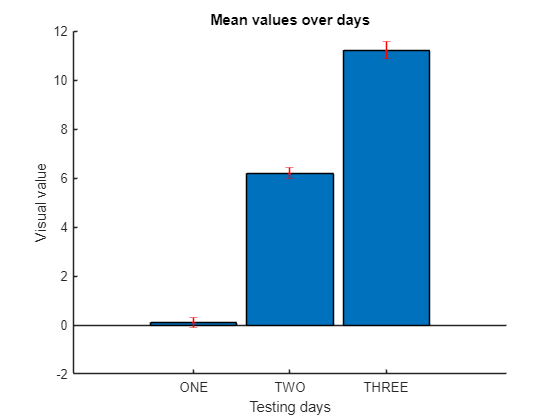

%% 8) Data visualization

% Display a boxplot and a violin plot of data during the three days of treatments.
% Hint of useful functions: boxplot or boxchart, repmat, swarmchart